## Data sampling for ID

### trim data

start_time = duration('00:03:35.148000');
end_time = duration('00:03:35.152000');

% Create a timerange object
ts_range = timerange(start_time, end_time);

% Index both pitch_in and elevator using the rows subscript
elevator_trim = pitch_in.pitch_in(ts_range,:) - elevator.elevator(ts_range,:)

elevator_trim = 0

throttle_trim = throttle_in.throttle_in(ts_range,:) - throttle.throttle(ts_range,:)

throttle_trim = 0.2347

airspeed_trim = ind_airspeed.indicated_airspeed(ts_range,:)

airspeed_trim = single
13.7724

alt_trim = alt.alt(ts_range,:)

alt_trim = single
556.9732

pitch_rate_trim = q.q(ts_range,:)

pitch_rate_trim = 0.3443

alpha_trim = alpha.alpha(ts_range,:)

alpha_trim = single
0.7386

### step input

t_start = duration('00:03:35.096000');
t_end_s = duration('00:03:45.068000');
t_end_p = duration('00:03:55.040000');

% sampling the short period inputs - 5 secs
% Create a timerange object
ts_range = timerange(t_start, t_end_s);
throttle_s_step = throttle_in.throttle_in(ts_range,:) - throttle_trim;
elevator_s_step = pitch_in.pitch_in(ts_range,:) - elevator_trim;
q_s_step = q.q(ts_range,:); 
aoa_s_step = alpha.alpha(ts_range,:);

%smapling phugoid inputs - atleast 10 secs
% Create a timerange object
ts_range = timerange(t_start, t_end_p);
throttle_p_step = throttle_in.throttle_in(ts_range,:) - throttle_trim;
elevator_p_step = pitch_in.pitch_in(ts_range,:) - elevator_trim;
vel_p_step = ind_airspeed.indicated_airspeed(ts_range,:); 
alt_p_step = alt.alt(ts_range,:);

### doublet input

t_start = duration('00:04:08.832000');
t_end_s = duration('00:04:15.200000');
t_end_p = duration('00:04:24.748000');
% sampling the short period inputs - 5 secs
% Create a timerange object
ts_range = timerange(t_start, t_end_s);
throttle_s_doublet = throttle_in.throttle_in(ts_range,:) - throttle_trim;
elevator_s_doublet = pitch_in.pitch_in(ts_range,:) - elevator_trim;
q_s_doublet = q.q(ts_range,:); 
aoa_s_doublet = alpha.alpha(ts_range,:);

%smapling phugoid inputs - atleast 10 secs
% Create a timerange object
ts_range = timerange(t_start, t_end_p);
throttle_p_doublet = throttle_in.throttle_in(ts_range,:) - throttle_trim;
elevator_p_doublet = pitch_in.pitch_in(ts_range,:) - elevator_trim;
vel_p_doublet = ind_airspeed.indicated_airspeed(ts_range,:); 
alt_p_doublet = alt.alt(ts_range,:);

### sine sweep input

t_start = duration('00:04:41.088000');
t_end_s = duration('00:05:01.032000');
t_end_p = duration('00:05:01.032000');
% sampling the short period inputs - 5 secs
% Create a timerange object
ts_range = timerange(t_start, t_end_s);
throttle_s_sine = throttle_in.throttle_in(ts_range,:) - throttle_trim;
elevator_s_sine = pitch_in.pitch_in(ts_range,:) - elevator_trim;
q_s_sine = q.q(ts_range,:); 
aoa_s_sine = alpha.alpha(ts_range,:);

%smapling phugoid inputs - atleast 10 secs
% Create a timerange object
ts_range = timerange(t_start, t_end_p);
throttle_p_sine = throttle_in.throttle_in(ts_range,:) - throttle_trim;
elevator_p_sine = pitch_in.pitch_in(ts_range,:) - elevator_trim;
vel_p_sine = ind_airspeed.indicated_airspeed(ts_range,:); 
alt_p_sine = alt.alt(ts_range,:);

## System ID script - step

iodelay = 0;
u1 = throttle_s_step;
u2 = elevator_s_step;
u3 = throttle_p_step;
u4 = elevator_p_step;
airspeed_trim = vel_p_step(1,1);
alt_trim = alt_p_step(1,1);
pitch_rate_trim = q_s_step(1,1);
alpha_trim = aoa_s_step(1,1);
y3 = q_s_step - pitch_rate_trim;
y1 = double(vel_p_step - airspeed_trim);
y4 = double(aoa_s_step - alpha_trim);
y5 = double(alt_p_step - alt_trim);

### MIMO identification - short period mode

u = [u2];
y = [y3 y4];
np = [3;2];%[3 3; 2 2];
nz = [1;2]%[1 1; 2 2];

nz =      1
     2


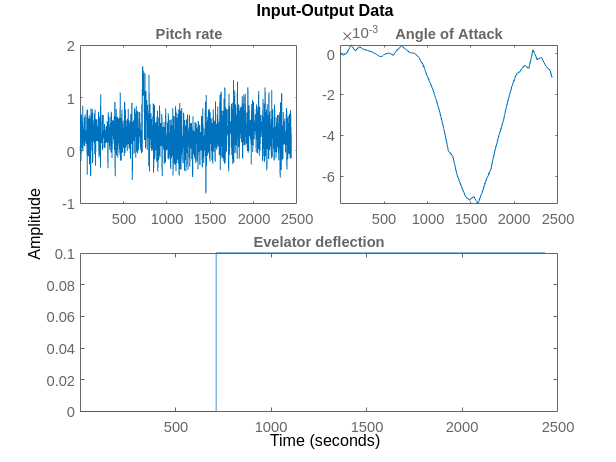

data = iddata(y,u);
set(data,'InputName',{'Evelator deflection'},'OutputName',{'Pitch rate', 'Angle of Attack'})
plot(data)

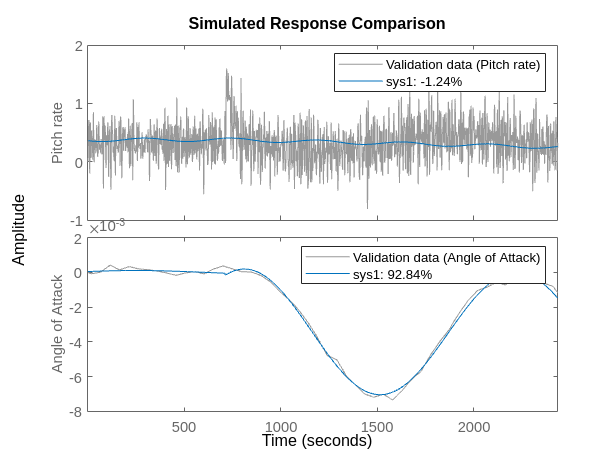

sys1= tfest(data,np,nz,iodelay);
compare(data,sys1)

### MIMO identification - Phugoid mode

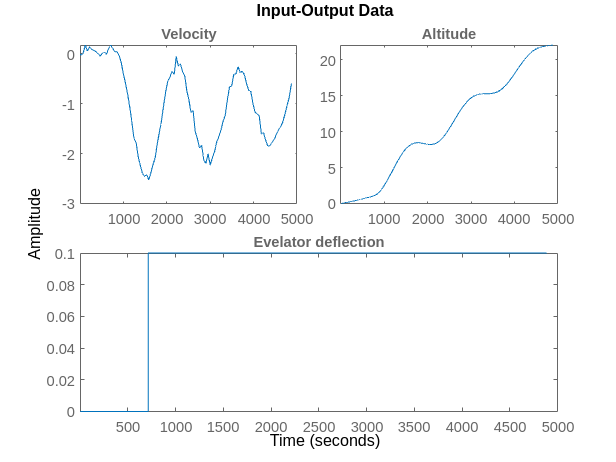

u = [u4];
y = [y1 y5];
np = [2;3];%[3 2; 3 3];
nz = [1;2];%[1 1; 2 2];
data = iddata(y,u);
set(data,'InputName',{'Evelator deflection'},'OutputName',{'Velocity', 'Altitude'});
plot(data)

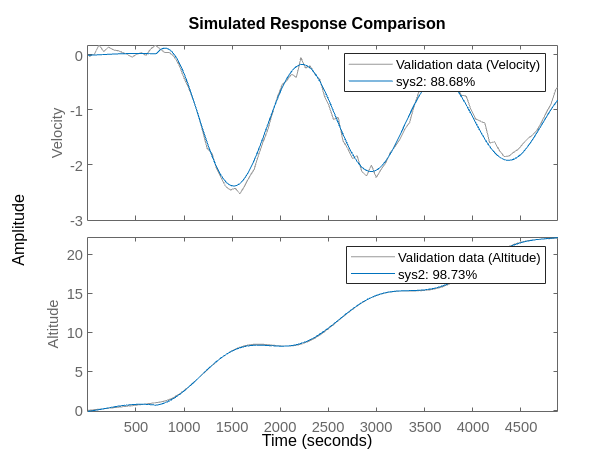

sys2= tfest(data,np,nz,iodelay);
compare(data,sys2)

### system identified

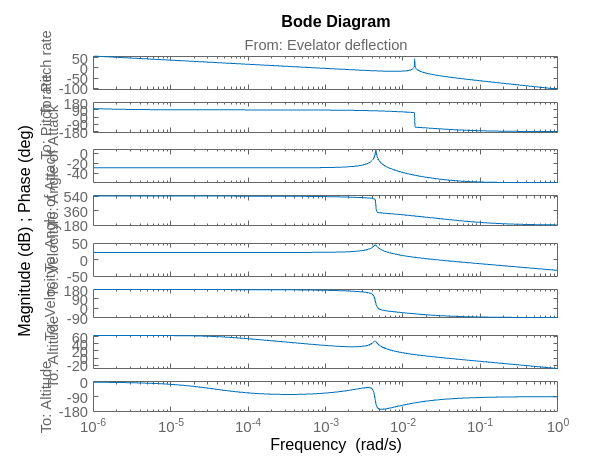

G1 = tf([sys1; sys2]);  %Inputs-Throttle, evelator & outputs-Pitchrate, aoa, velocity, height
bode(G1)

## System ID script - doublet

iodelay = 0;
u1 = throttle_s_doublet-0.05;
u2 = elevator_s_doublet;
u3 = throttle_p_doublet-0.05;
u4 = elevator_p_doublet;
airspeed_trim = vel_p_doublet(1,1);
alt_trim = alt_p_doublet(1,1);
pitch_rate_trim = q_s_doublet(1,1);
alpha_trim = aoa_s_doublet(1,1);
y1 = double(vel_p_doublet - airspeed_trim);
y3 = q_s_doublet - pitch_rate_trim;
y4 = double(aoa_s_doublet - alpha_trim);
y5 = double(alt_p_doublet - alt_trim);

### MIMO identification - short period mode

u = [u2];
y = [y3 y4];
np = [3;2];%[3 3; 2 2];
nz = [1;2]%[1 1; 2 2];

nz =      1
     2


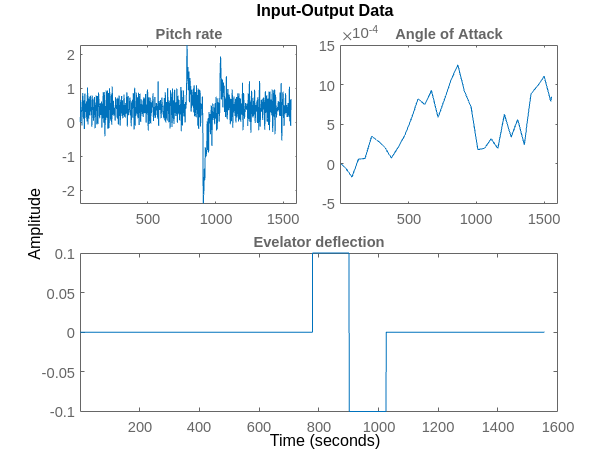

data = iddata(y,u);
set(data,'InputName',{'Evelator deflection'},'OutputName',{'Pitch rate', 'Angle of Attack'})
plot(data)

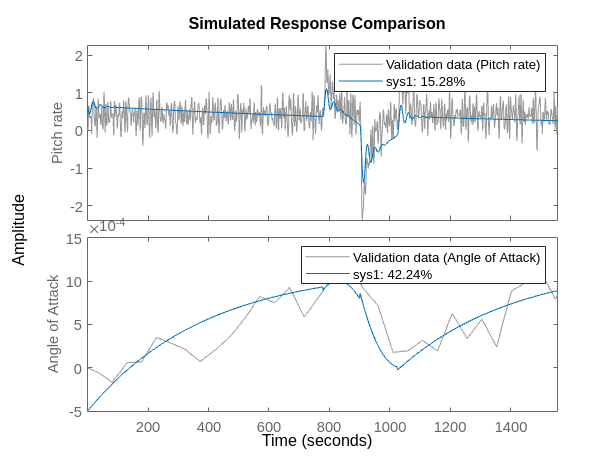

sys1= tfest(data,np,nz,iodelay);
compare(data,sys1)

### MIMO identification - Phugoid mode

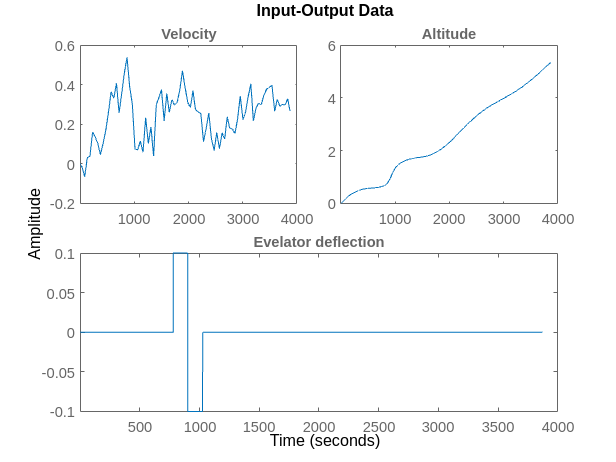

u = [u4];
y = [y1 y5];
np = [2;3];%[3 2; 3 3];
nz = [1;2];%[1 1; 2 2];
data = iddata(y,u);
set(data,'InputName',{'Evelator deflection'},'OutputName',{'Velocity', 'Altitude'});
plot(data)

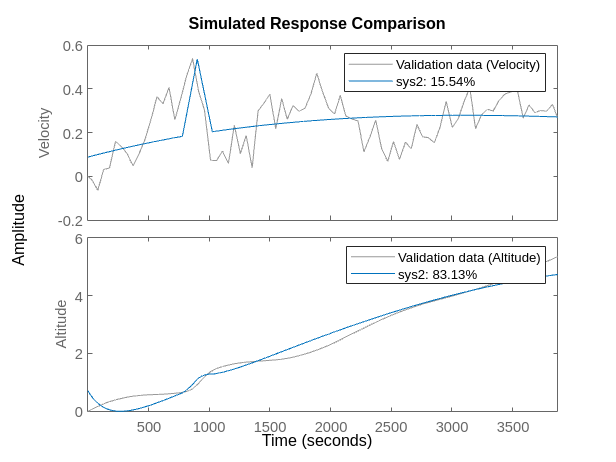

sys2= tfest(data,np,nz,iodelay);
compare(data,sys2)

### system identified

G2_e = tf([sys1; sys2])  %Inputs-Throttle, evelator & outputs-Pitchrate, aoa, velocity, height

G2_e =
 
  From input "Evelator deflection" to output...
                          0.3447 s - 0.003838
   Pitch rate:  ---------------------------------------
                s^3 + 0.0871 s^2 + 0.06878 s + 5.03e-05
 
                     -0.000376 s^2 + 3.865e-05 s - 8.58e-07
   Angle of Attack:  --------------------------------------
                          s^2 + 0.002563 s + 3.18e-16
 
                  0.02782 s + 1.243e-05
   Velocity:  -----------------------------
              s^2 + 0.0003758 s + 9.923e-08
 
                0.007363 s^2 + 0.0003231 s + 4.649e-08
   Altitude:  -------------------------------------------
              s^3 + 0.005882 s^2 + 1.33e-07 s + 7.822e-10
 
Continuous-time transfer function.



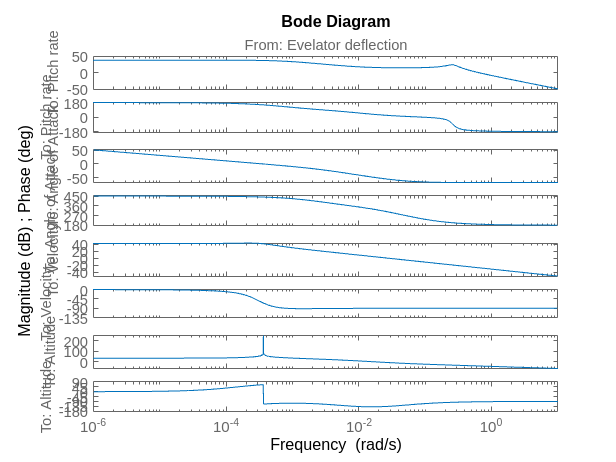

bode(G2_e)

## System ID script - sine sweep

iodelay = 0;
u1 = throttle_s_sine;
u2 = elevator_s_sine;
u3 = throttle_p_sine;
u4 = elevator_p_sine;
airspeed_trim = vel_p_sine(1,1);
alt_trim = alt_p_sine(1,1);
pitch_rate_trim = q_s_sine(1,1);
alpha_trim = aoa_s_sine(1,1);
y1 = double(vel_p_sine - airspeed_trim);
y3 = q_s_sine - pitch_rate_trim;
y4 = double(aoa_s_sine - alpha_trim);
y5 = double(alt_p_sine - alt_trim);

### MIMO identification - short period mode

u = [u2];
y = [y3 y4];
np = [3;2];%[3 3; 2 2];
nz = [1;2]%[1 1; 2 2];

nz =      1
     2


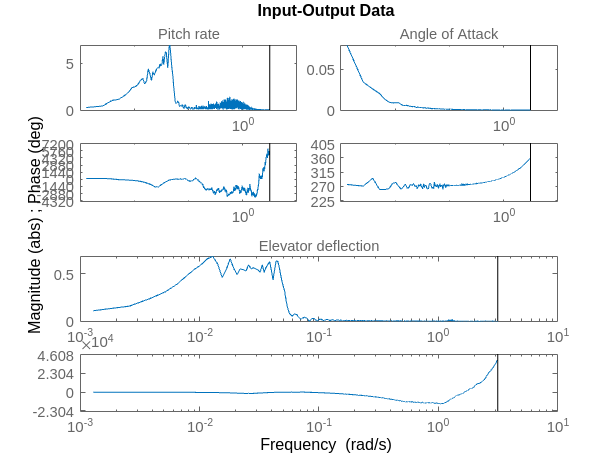

data = iddata(y,u);
data = fft(data);
set(data,'InputName',{'Elevator deflection'},'OutputName',{'Pitch rate', 'Angle of Attack'})
plot(data)

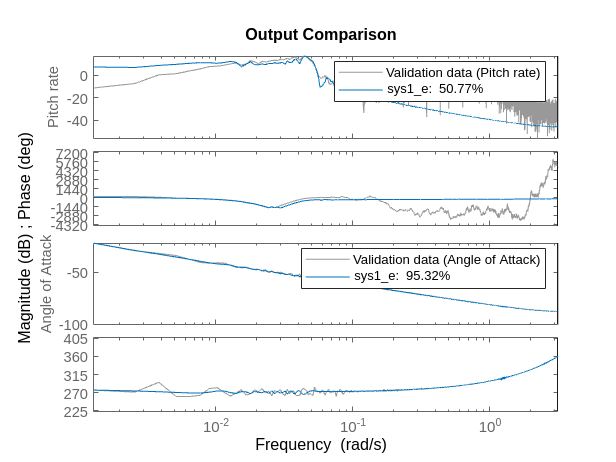

sys1_e= tfest(data,np,nz,iodelay);
compare(data,sys1_e)

### MIMO identification - Phugoid mode

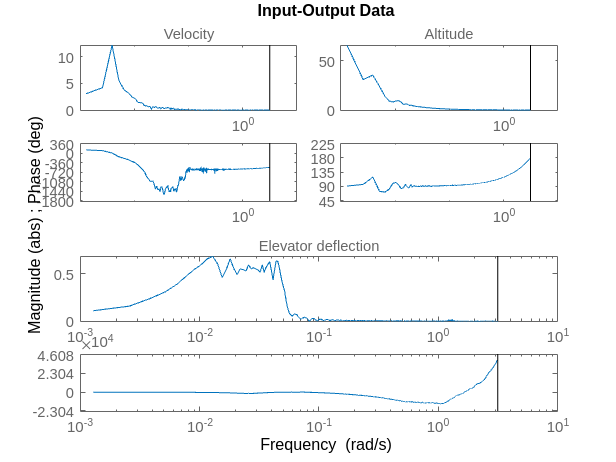

u = [u4];
y = [y1 y5];
np = [2;3];%[3 2; 3 3];
nz = [1;2];%[1 1; 2 2];
data = iddata(y,u);
data = fft(data);
set(data,'InputName',{'Elevator deflection'},'OutputName',{'Velocity', 'Altitude'})
plot(data)

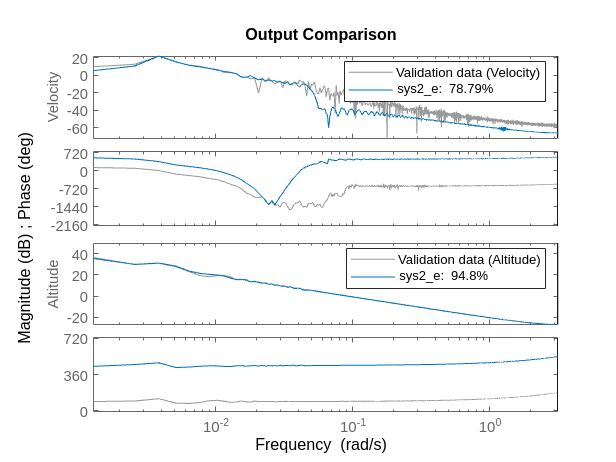

sys2_e= tfest(data,np,nz,iodelay);
compare(data,sys2_e)

### system identified

G3_e = tf([sys1_e; sys2_e])  %Inputs-Throttle, evelator & outputs-Pitchrate, aoa, velocity, height

G3_e =
 
  From input "Elevator deflection" to output...
                          0.01629 s - 0.0001404
   Pitch rate:  ------------------------------------------
                s^3 - 0.01448 s^2 + 0.003604 s - 4.773e-07
 
                     0.0002953 s^2 - 1.522e-06 s - 4.993e-08
   Angle of Attack:  ---------------------------------------
                          s^2 - 0.0003445 s + 1.975e-07
 
                  0.02005 s - 0.0002072
   Velocity:  -----------------------------
              s^2 + 0.0009335 s + 1.631e-05
 
                -0.009588 s^2 - 8.038e-06 s + 2.53e-07
   Altitude:  -------------------------------------------
              s^3 + 0.0007269 s^2 + 1.83e-05 s - 5.81e-09
 
Continuous-time transfer function.



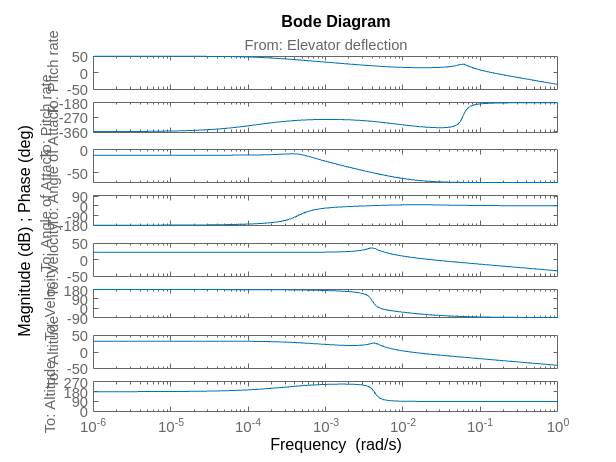

bode(G3_e)